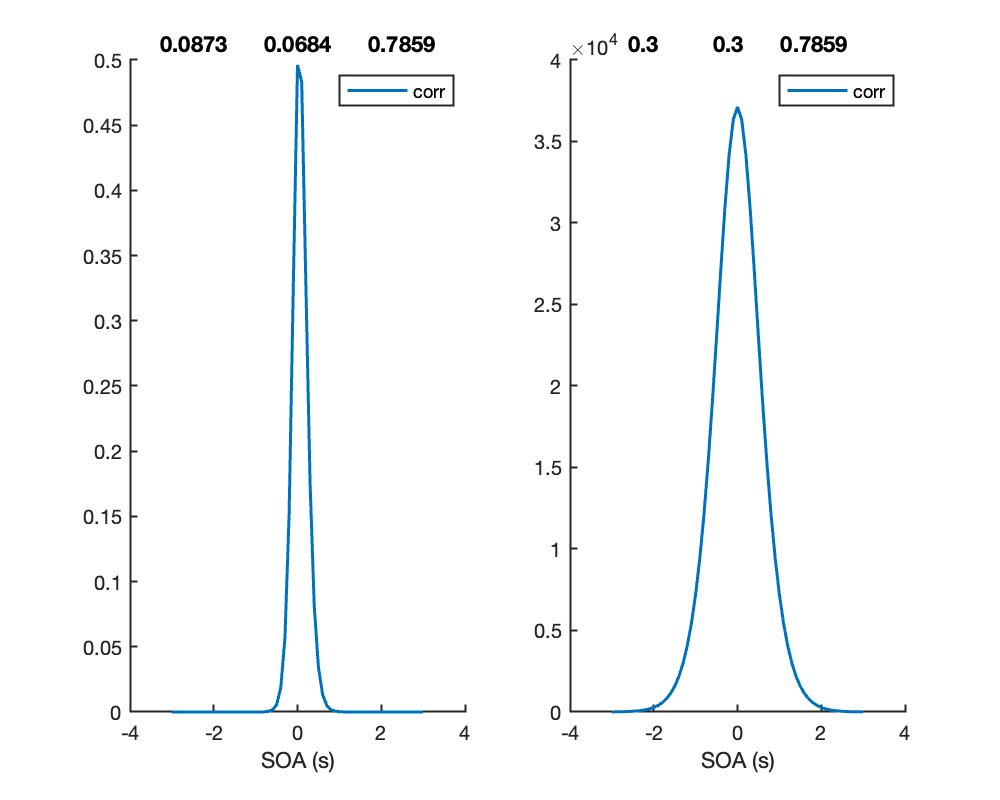

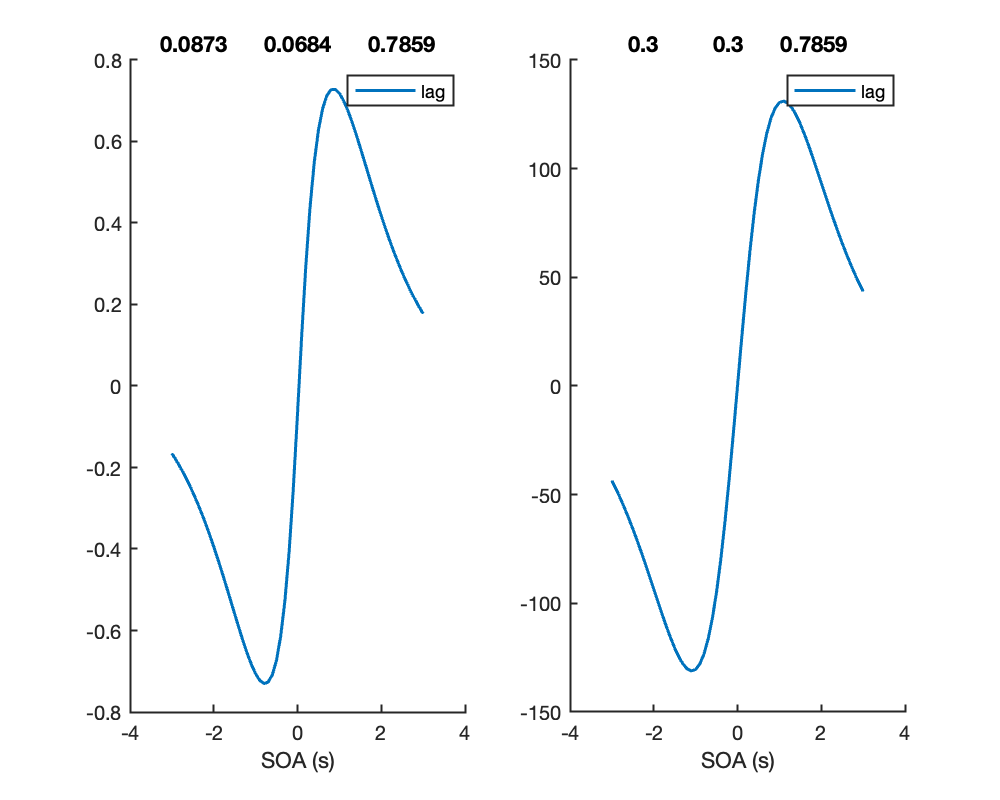

% This script test a different set of of AV tau and plots MCD_corr and MCD_lag to look
% at its absolute range

clear all; close all; clc; rng('shuffle');

%% set parameters
fs                          = 1e3; % hz
stim_dura                   = 0.033; % in sec
ts_duration                 = 16; % in sec, 7 x 2 padding + 2 stimulus duration

%% for a range of soa
soas                        = [-3:0.1:3]; % in sec

% temporal constants
params                      = [0.0873, 0.0684, 0.7859; % default tv, ta, tav
    0.3, 0.3, 0.7859]; % testing tv, ta, tav

f1                          = figure;
f2                          = figure;
f3                          = figure;

for s                       = 1:2 % test two sets of parameters
    % initiate
    nsample                     = ts_duration * fs + 1;
    t                           = linspace(0, ts_duration, nsample);

    % low-pass filters (Equation 1)
    param                       = params(s,:);
    fv                          = fft(t.*exp(-t./param(1)));
    fa                          = fft(t.*exp(-t./param(2)));
    fav                         = fft(t.*exp(-t./param(3)));

    for i                       = 1:numel(soas)
        soa                         = -soas(i);

        %% reconstruct signals

        % initiate empty time seris
        stimV                       = zeros([1, nsample]); % reset v signals
        stimA                       = zeros([1, nsample]); % reset v signals
        midpoint                    = ts_duration/2 * fs + 1; % soa are centered around this midpoint

        % note that soa_m are rounded to be split into half and be centered around the midpoint
        half_soa                    = round(soa/2 * fs);

        % find out index of a/v stimulus onset and offset
        t_v_onset                   = midpoint + half_soa;
        t_v_offset                  = t_v_onset + stim_dura * fs;

        t_a_onset                   = midpoint - half_soa;
        t_a_offset                  = t_a_onset + stim_dura * fs;

        % assign 1 to stimulus inpulse
        stimV(t_v_onset:t_v_offset) = 1;
        stimA(t_a_onset:t_a_offset) = 1;

        %     % plot to check signals
        %     figure; hold on
        %     plot(stimA); plot(stimV);

        % early filtering
        st_v                        = fft(stimV).*fv;
        st_a                        = fft(stimA).*fa;

        % late filtering
        st_v_av                     = ifft(st_v.*fav);
        st_a_av                     = ifft(st_a.*fav);

        % xcorrelate
        u1                          = st_a_av.*ifft(st_v);         % Equation 2
        u2                          = st_v_av.*ifft(st_a);         % Equation 3

        % MCD correlation detector output
        MCD_corr_signal             = u2.*u1;         % Equation 4
        MCD_corr(i)                 = mean(MCD_corr_signal); % Equation 6

        % MCD lag detector output
        MCD_lag_signal              = u2-u1;           % Equation 5
        MCD_lag(i)                  = mean(MCD_lag_signal);   % Equation 7

    end

    % plot
    figure(f1); % plot corr and lag together
    subplot(1,2,s); hold on
    title(num2str(param))
    set(gca, 'LineWidth', 1, 'FontSize', 10)
    set(gcf, 'Position',[10 10 500 400])
    plot(soas, MCD_corr,'LineWidth',1.5)

    xlabel('SOA (s)')
    legend({'corr', 'lag'})

    %% plot corr
    figure(f2); % plot corr together to look at scale
    subplot(1,2,s); hold on
    title(num2str(param))
    set(gca, 'LineWidth', 1, 'FontSize', 10)
    set(gcf, 'Position',[10 10 500 400])
    plot(soas, MCD_corr,'LineWidth',1.5)
    xlabel('SOA (s)')
    legend({'corr'})

    %% plot lag
    figure(f3);
    subplot(1,2,s); hold on
    title(num2str(param))
    set(gca, 'LineWidth', 1, 'FontSize', 10)
    set(gcf, 'Position',[10 10 500 400])
    plot(soas, MCD_lag,'LineWidth',1.5)
    xlabel('SOA (s)')
    legend({'lag'})
end


% two problems with MCD model:
% 1) lag becomes nonlinear when abs(SOA)>1.
% 2) corr can be extremely big under certain tau combinations (when
% tau gets bigger); lag is better, but the unit also becomes huge.